## Lip and tongue spectral fluorescence across subjects and levels

We combined data from specific dates for both the 405 nm and 415 nm excitation lights for the four different subjects. We did this separately for lip and tongue.  

The lip and tongue data from the multiple subjects are generally similar, which is clear from the semilogy plots. There is aAnother detailed look at the individual subjects is in **s_oeCompareSubjects.mlx**.

In** s_oeDataRange.mlx** we concluded that 405 and 415 are not distinguishable, but 450 nm excitation differs.  So here we combined the 405-415 in our plots.  The conclusions are

- The negative slopefor the lip  is steeper than the tongue between 500-600nm, for all three excitation lights

- The lip and tongue seem to have a rise and then negative slope from 580 to 700nm.  This is likely present for all three ex lights

- The 405/415 lights excite the porphyrins, which mask the tissue fluorophores, but the 450 nm ex light does not and we can see the normal tissue fluorophores.

**Thoughts**

The keratinized areas of the dorsal surface of the tongue (e.g., filiform papillae) likely absorb less light due to increased reflectance from keratin.

The non-keratinized areas of the lower innner lip oral mucosal tissue absorbs more light than keratinized regions due to less reflectance. The inner lip epithelium is generally thicker than the dorsal tongue epithelium, potentially leading to increased light absorption. The rich vascular network in the lip may contribute to greater absorbance by blood compared to the tongue.

ieInit;
waves = 500:5:700;
nWave = 520; %580;
yScale = 'linear';
T = oeDatabaseCreate;

## Lip data

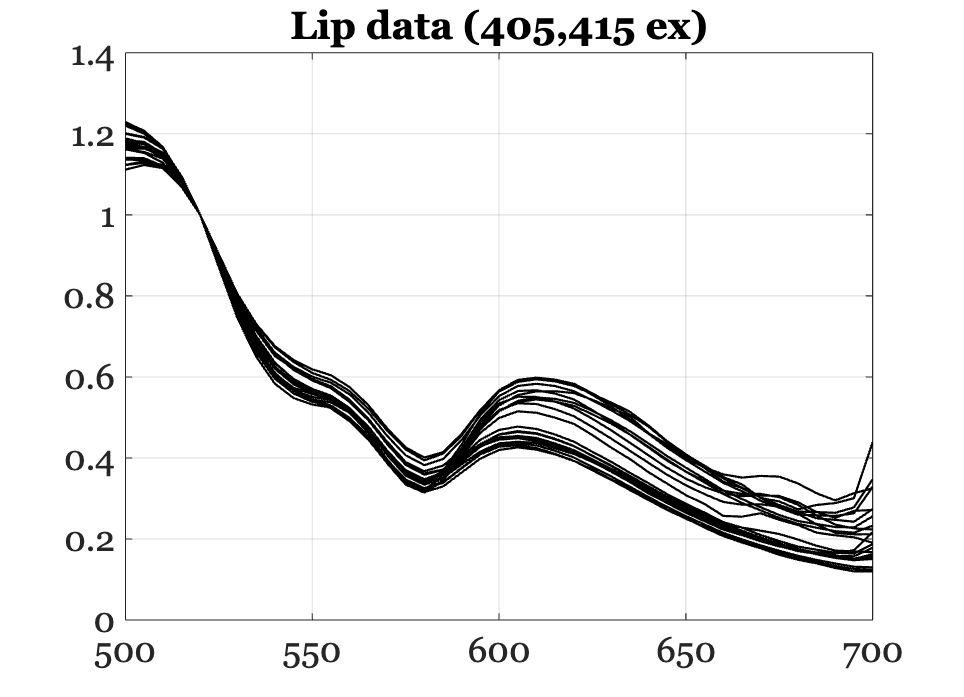

% We only want these dates.
[~,tRows] = ieTableGet(T,'date','2024-03-12','date','2024-03-14','date','2024-03-19','operator','or');

lipFiles405 = ieTableGet(tRows,'ewave',405,'substrate','lip');
lipFiles415 = ieTableGet(tRows,'ewave',415,'substrate','lip');
lipFiles = cat(1,lipFiles405,lipFiles415);
dataLip = oeReadFiles(lipFiles,'waves',waves,'normalized wave',nWave);

symbolsLip = {'kx-','k*-','k^-','ko-'};

ieFigure;
for ii= 1:numel(lipFiles)
    plot(waves,dataLip(:,ii),'k-'); hold on; 
    set(gca,'yscale',yScale);
end
grid on;
title('Lip data (405,415 ex)')

## Tongue data

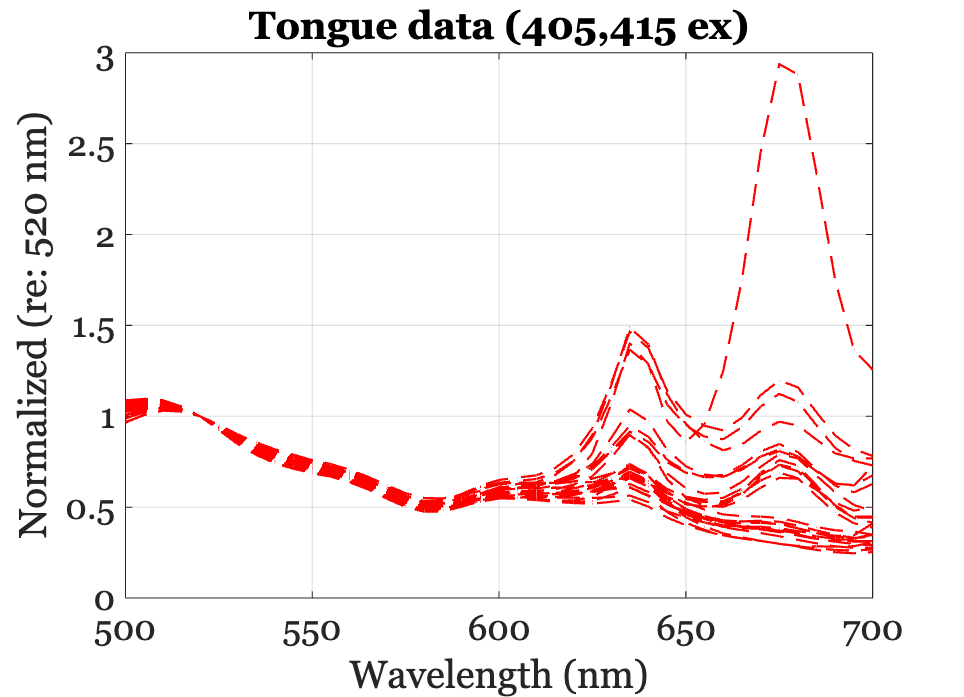

tongueFiles405 = ieTableGet(tRows,'ewave',405,'substrate','tongue');
tongueFiles415 = ieTableGet(tRows,'ewave',415,'substrate','tongue');
tongueFiles = cat(1,tongueFiles405,tongueFiles415);
dataTongue = oeReadFiles(tongueFiles,'waves',waves,'normalized wave',nWave);

symbolsTongue = {'rx-','r*-','r^-','ro-'};

ieFigure;
for ii= 1:numel(tongueFiles)
    plot(waves,dataTongue(:,ii),'r--'); hold on;
    set(gca,'yscale',yScale);
end
grid on;
xlabel('Wavelength (nm)')
if isempty(nWave), ylabel('Energy (watts/sr/nm/m^2)');
else, ylabel(sprintf('Normalized (re: %d nm)',nWave));
end
title('Tongue data (405,415 ex)')

## Mean Lip and Tongue

The mean slope for the Tongue differs from the slope for the Lip (steeper) between 500 and 600.

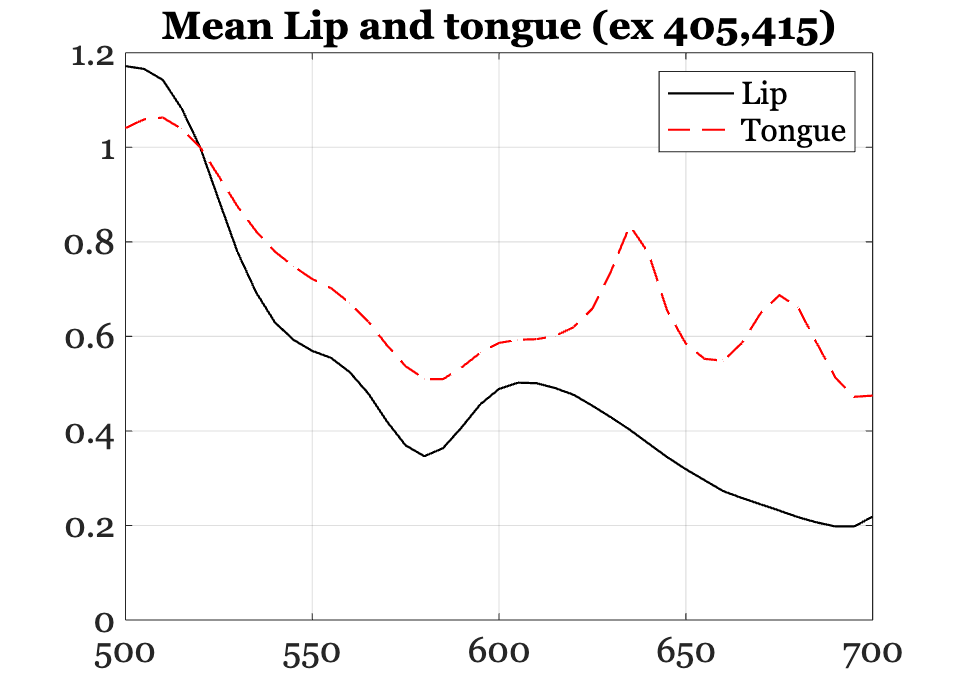

ieFigure;
hA = plot(waves,mean(dataLip,2),'k-'); hold on;
hB = plot(waves,mean(dataTongue,2),'r--'); hold on;
set(gca,'yscale',yScale);
grid on

title('Mean Lip and tongue (ex 405,415)');
legend([hA,hB],{'Lip','Tongue'});

## Lip and Tongue compared at 415

For all of the subjects, the slope for the Tongue differs from the slope for the Lip (steeper) between 500 and 600.

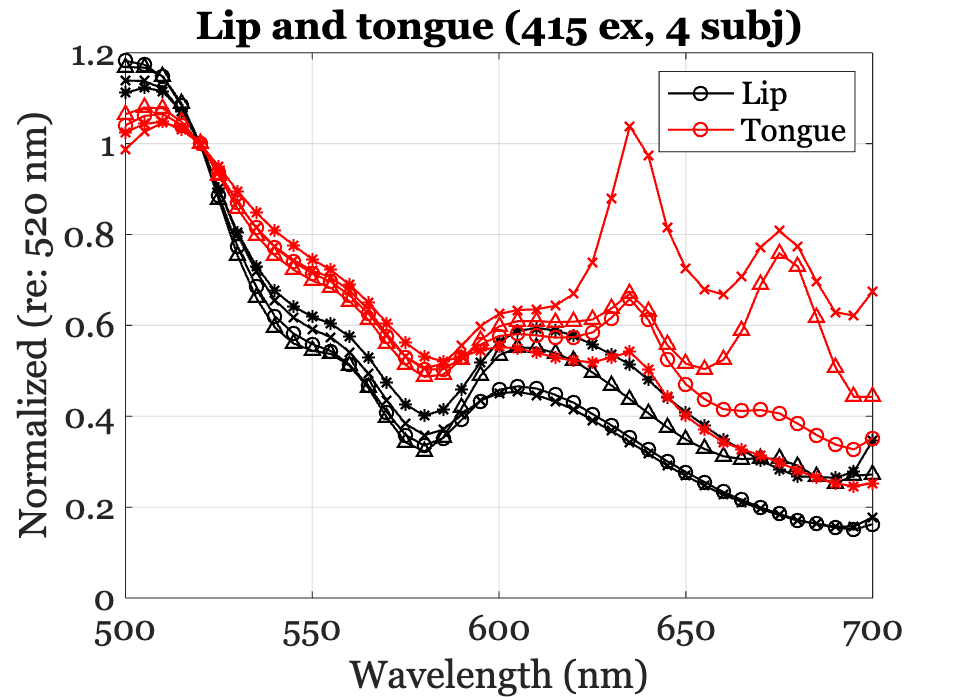

lipFiles415 = ieTableGet(T,'ewave',415,'substrate','lip','elevel',910);
symbols = {'kx-','k*-','k^-','ko-'};
% Collected on the same day as above.
selected = [11,12,13,14];
lipFiles415 = lipFiles415(selected);
data = oeReadFiles(lipFiles415,'waves',waves,'normalized wave',nWave);

ieNewGraphWin;
for ii= 1:numel(lipFiles415)
    hA = plot(waves,data(:,ii),symbols{ii}); hold on; 
    set(gca,'yscale',yScale);
end

tongueFiles415 = ieTableGet(T,'ewave',415,'substrate','tongue','elevel',910);
tongueFiles415 = tongueFiles415(selected);
data = oeReadFiles(tongueFiles415,'waves',waves,'normalized wave',nWave);
symbols = {'rx-','r*-','r^-','ro-'};

for ii= 1:numel(tongueFiles415)
    hB = plot(waves,data(:,ii),symbols{ii}); hold on; 
    set(gca,'yscale',yScale);
end

grid on;
xlabel('Wavelength (nm)')
if isempty(nWave), ylabel('Energy (watts/sr/nm/m^2)');
else, ylabel(sprintf('Normalized (re: %d nm)',nWave));
end

legend([hA,hB],{'Lip','Tongue'});
title('Lip and tongue (415 ex, 4 subj)');

## Analysis at 450nm

The same is true for the 450 nm excitation.

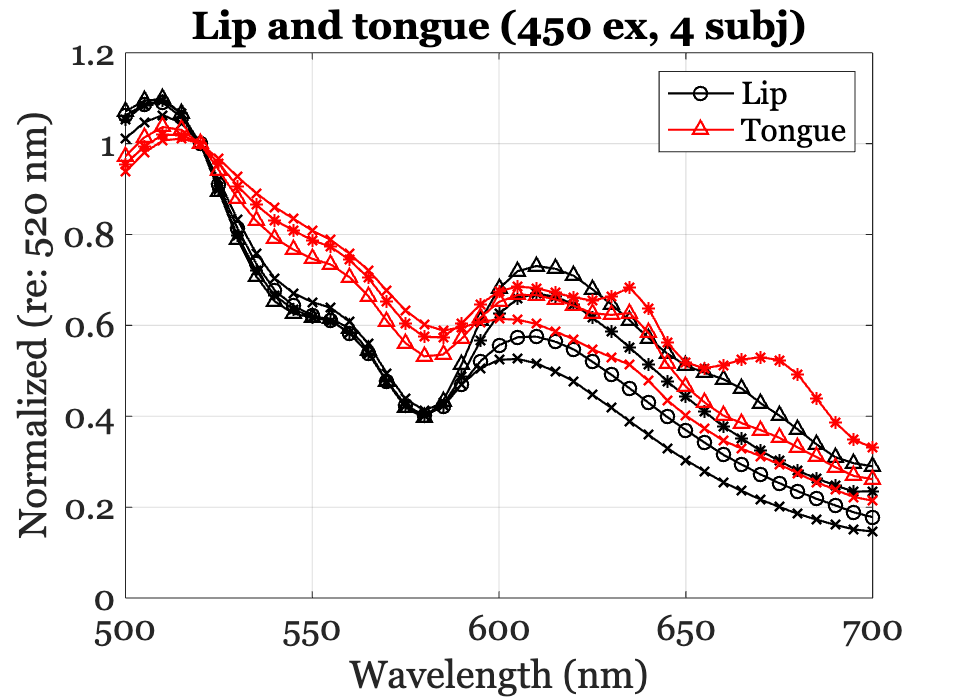

symbols = {'kx-','k*-','k^-','ko-'};
lipFiles450 = ieTableGet(T,'ewave',450,'substrate','lip','elevel',870,'return','files');
dataLip450 = oeReadFiles(lipFiles450,'waves',waves,'normalized wave',nWave);
ieNewGraphWin;
for ii= 1:numel(lipFiles450)
    hA = plot(waves,dataLip450(:,ii),symbols{ii}); hold on; 
    set(gca,'yscale',yScale);
end

symbols = {'rx-','r*-','r^-','ro-'};
tongueFiles450 = ieTableGet(T,'ewave',450,'substrate','tongue','elevel',870,'return','files');
% Collected on the same day as above.
dataTongue450 = oeReadFiles(tongueFiles450,'waves',waves,'normalized wave',nWave);

for ii= 1:numel(tongueFiles450)
    hB = plot(waves,dataTongue450(:,ii),symbols{ii}); hold on;
end

grid on;
xlabel('Wavelength (nm)')
if isempty(nWave), ylabel('Energy (watts/sr/nm/m^2)');
else, ylabel(sprintf('Normalized (re: %d nm)',nWave));
end
legend([hA,hB],{'Lip','Tongue'});
title('Lip and tongue (450 ex, 4 subj)');

## **Compare Lip and Tongue with 450 nm ex (means)**

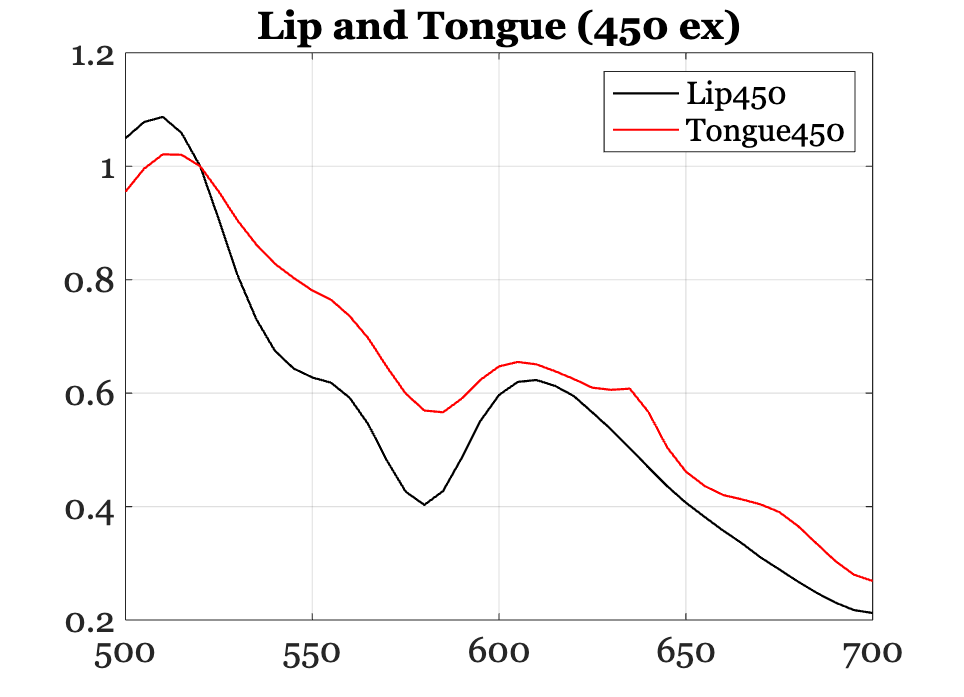

ieFigure;
hA = plot(waves,mean(dataLip450,2),'k-'); hold on;
hB = plot(waves,mean(dataTongue450,2),'r-'); hold on;
grid on
set(gca,'yscale',yScale);
title('Lip and Tongue (450 ex)')
legend([hA,hB],{'Lip450','Tongue450'});